## **Forward TRF example**

This example script loads and preprocesses a publicly available electroencephalography (EEG) dataset (the diliBach dataset, [https://doi.org/10.7554/eLife.51784,](https://doi.org/10.7554/eLife.51784,) [https://datadryad.org/stash/dataset/doi:10.5061/dryad.g1jwstqmh](https://datadryad.org/stash/dataset/doi:10.5061/dryad.g1jwstqmh)). The same script can be applied to other datasets (see the list of datasets here: [https://cnspworkshop.net/resources.html).](https://cnspworkshop.net/resources.html).) EEG signals were recorded as participants listened to monophonic Bach melodies. A drop down box is provided in the code for exploring other datasets. In this example, we also provide access to the LalorNatSpeech speech listening-EEG dataset.  

'dataStim.mat' contains the stimulus features. 'pre_dataSub1.mat' contains the preprocessed EEG signals (see [https://pubmed.ncbi.nlm.nih.gov/37744463/](https://pubmed.ncbi.nlm.nih.gov/37744463/)). Then, the script runs a typical forward TRF analysis to measure how strongly the EEG signals encode specific stimulus features, such as the sound envelope and the note onsets.

Note: Please see [https://cnspworkshop.net](https://cnspworkshop.net) and [https://diliberg.net](https://diliberg.net) for additional resources such as tutorials, videotutorials, and datasets.

Author: Giovanni M. Di Liberto ([https://diliberg.net](https://diliberg.net)) 

Please cite:

- mTRF-Toolbok: [https://www.frontiersin.org/articles/10.3389/fnhum.2016.00604/full](https://www.frontiersin.org/articles/10.3389/fnhum.2016.00604/full) 

- Open science framework: [https://nbdt.scholasticahq.com/article/124867-a-standardised-open-science-framework-for-sharing-and-re-analysing-neural-data-acquired-to-continuous-stimuli](https://nbdt.scholasticahq.com/article/124867-a-standardised-open-science-framework-for-sharing-and-re-analysing-neural-data-acquired-to-continuous-stimuli) 

Please check out

- mTRF-Toolbox - Considerations for applied research: [https://www.frontiersin.org/journals/neuroscience/articles/10.3389/fnins.2021.705621/full](https://www.frontiersin.org/journals/neuroscience/articles/10.3389/fnins.2021.705621/full) 

- Original study for the diliBach dataset: [https://elifesciences.org/articles/51784](https://elifesciences.org/articles/51784) 

- CND dataset available here: [https://cnspworkshop.net/resources.html](https://cnspworkshop.net/resources.html) 

### Workspace setup

This section clears the workspace and adds the library folders to the Matlab paths

clear all
close all

addpath ./examples/libs/cnsp_utils
addpath ./examples/libs/cnsp_utils/cnd
addpath ./mtrf
addpath ./examples/libs/filedownload

Forward TRF example live-script


### Data preparation

This section downloads the sample data. This sample dataset consists of 64-channel EEG time-series from two distinct individuals (pre_dataSub files; note that the original dataset includes data from 20 participants). The signals were filtered between 1 and 8 Hz and downsampled to 64Hz. The dataStim.mat file contains features of the corresponding music stimulus (i.e., Hilbert envelope and note onsets). dataStim is the input of a forward mTRF model. dataSub is the output of a forward mTRF model.

% Sample data from speech or music EEG datasets
datasetName = 'LalorNatSpeech';

% Creating directory where the sample data will be downloaded
if ~exist(datasetName, 'dir')
    mkdir(datasetName)
end

% Setting up filenames and URL
stimFilename = "dataStim.mat";
eegFilenames = {'pre_dataSub1.mat','pre_dataSub2.mat'};

dataStim_URL = "https://www.data.cnspworkshop.net/sampleData/"+datasetName+"/"+stimFilename;

% Download stimulus file
if ~isfile(datasetName+"/"+stimFilename)
    downloadFile(datasetName+"/"+"dataStim.mat", dataStim_URL, ShowFilename=true)
else
    disp('Skipping download. Stim file already present.')
end

Skipping download. Stim file already present.



% Download neural data file
for iiSub = 1:length(eegFilenames)
    dataSub_URL = "https://www.data.cnspworkshop.net/sampleData/"+datasetName+"/"+eegFilenames{iiSub};

    if ~isfile(datasetName+"/"+eegFilenames{iiSub})
        downloadFile(datasetName+"/"+eegFilenames{iiSub}, dataSub_URL, ShowFilename=true)
    else
        disp('Skipping download. EEG file already present.')
    end

end

Skipping download. EEG file already present.
Skipping download. EEG file already present.


 
nSubs = length(eegFilenames);

% Loading Stimulus data
stimFilename = datasetName+"/"+"dataStim.mat";
load(stimFilename,'stim')

stim = cndNormalise(stim);

% Load list of stimulus features
stimNames = stim.names;

### Forward mTRF model fit

Setting up mTRF hyperparameters

tmin = -200;
tmax = 600;
lambdas = 10.^(-4:2:4); % small set of lambdas (quick)
% lambdas = 10.^(-6:1:6); % larger set of lambdas (slower)
dirTRF = 1; % Forward TRF model

stimName = stimNames(1); % Stimulus feature to use in the model fit
stimIdx = find(strcmp(stim.names,stimName));

if tmin > tmax
    disp('Warning: tmin > tmax; setting tmax=tmin for the analysis')
    tmax = tmin;
end


Loading preprocessed EEG data

subIdx = 1;
eegFilename = datasetName+"/"+eegFilenames{subIdx}; 
load(eegFilename,'eeg')

eeg = cndNormalise(eeg); % Standardise neural data (preserving the ratio between channels)

Making sure that stim and neural data have the same length. The trial may end a few seconds after the end of the audio e.g., the neural data may include the break between trials. It would be best to do this chunking at preprocessing, but let's check here, just to be sure. The function returnes a version of stim and eeg where their lengths have been made equal by cutting the tail of the longer time-series where necessary.

if eeg.fs < stim.fs
    stim = cndDownsample(stim,eeg.fs);
end

Processing CND: Downsampling from fs = 128 to downFs = 64



[stim,eeg] = cndCheckStimNeural(stim,eeg);

Forward TRF (unregularised)

model = mTRFtrain(stim.data(stimIdx,:),eeg.data,eeg.fs,dirTRF,tmin,tmax,0,'verbose',0);

Plot TRF weights

disp("Forward TRF weights (without regularisation)")

Forward TRF weights (without regularisation)


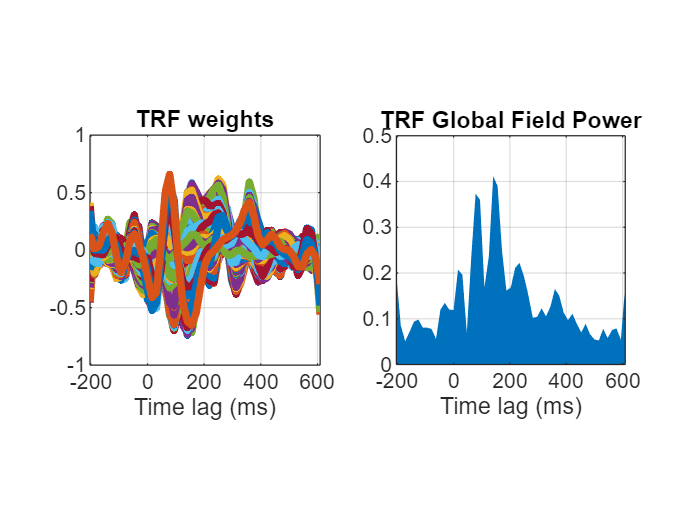


figure;
subplot(1,2,1)
mTRFplot(model,'trf');
title('TRF weights')
grid on

% Plot GFP
subplot(1,2,2)
mTRFplot(model,'gfp',[],'all');
title('TRF Global Field Power')
grid on

### Model tuning

Determine optimal lambda

[stats,t] = mTRFcrossval(stim.data(stimIdx,:),eeg.data,eeg.fs,dirTRF,tmin,tmax,lambdas,'verbose',0);
    
% Calculating optimal lambda. Display and store results
[maxR,bestLambda] = max(squeeze(mean(mean(stats.r,1),3)));
disp(['EEG prediction correlation (r) = ',num2str(maxR)])

EEG prediction correlation (r) = 0.0079448


rAll(subIdx) = maxR;
rAllElec(:,subIdx) = squeeze(mean(stats.r(:,bestLambda,:),1));
disp(['Average EEG pred corr (r) = ',num2str(mean(rAll))])

Average EEG pred corr (r) = 0.0079448



% Fit TRF model with optimal regularisation parameter
model = mTRFtrain(stim.data(stimIdx,:),eeg.data,eeg.fs,dirTRF,tmin,tmax,lambdas(bestLambda),'verbose',0);

% Store TRF model
modelAll(subIdx) = model;


Plot TRF weights of fine-tuned model

disp("Forward TRF weights (with regularisation)")

Forward TRF weights (with regularisation)


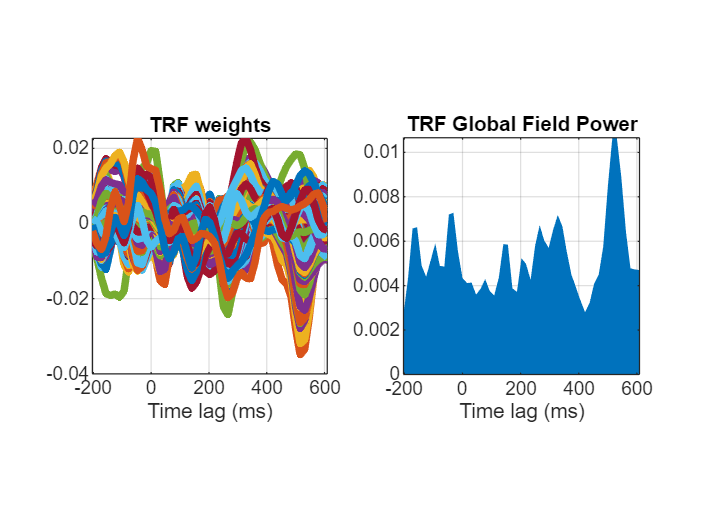


figure;
subplot(1,2,1)
mTRFplot(model,'trf');
title('TRF weights')
grid on

% Plot GFP
subplot(1,2,2)
mTRFplot(model,'gfp',[],'all');
title('TRF Global Field Power')
grid on

### Combining data from multiple subjects

Loading EEG data for participant 2. Note that all this is typically run with for loops. As an example, we have unpacked the loops here. The code that follows is largely the same as what was run for participant 1 above.

subIdx = 2;
eegFilename = datasetName+"/"+eegFilenames{subIdx}; 
load(eegFilename,'eeg')

eeg = cndNormalise(eeg); % Standardise neural data (preserving the ratio between channels)

Making sure that stim and neural data have the same length.

[stim,eeg] = cndCheckStimNeural(stim,eeg);

Determine optimal lambda

[stats,t] = mTRFcrossval(stim.data(stimIdx,:),eeg.data,eeg.fs,dirTRF,tmin,tmax,lambdas,'verbose',0);
    
% Calculating optimal lambda. Display and store results
[maxR,bestLambda] = max(squeeze(mean(mean(stats.r,1),3)));
disp(['r = ',num2str(maxR)])

r = 0.0065719


rAll(subIdx) = maxR;
rAllElec(:,subIdx) = squeeze(mean(stats.r(:,bestLambda,:),1));
disp(['Mean r = ',num2str(mean(rAll))])

Mean r = 0.0072584



% Fit TRF model with optimal regularisation parameter
model = mTRFtrain(stim.data(stimIdx,:),eeg.data,eeg.fs,dirTRF,tmin,tmax,lambdas(bestLambda),'verbose',0);

% Store TRF model
modelAll(subIdx) = model;


Plot TRF weights of fine-tuned model

disp("Forward TRF weights (participant 2; with regularisation)")

Forward TRF weights (participant 2; with regularisation)


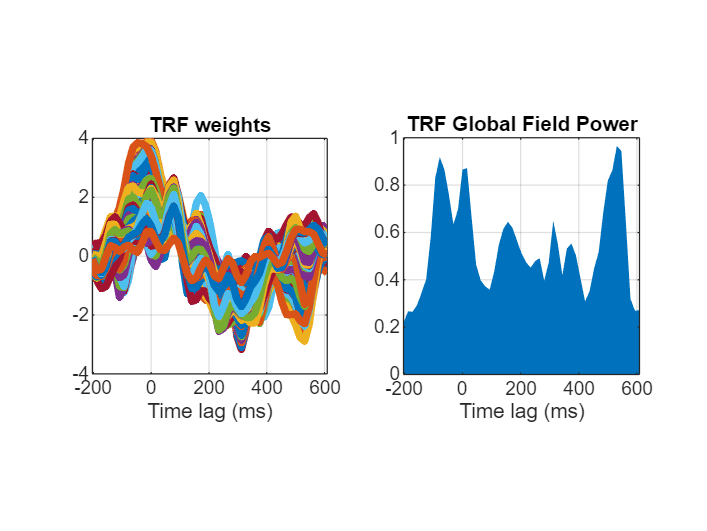


figure;
subplot(1,2,1)
mTRFplot(model,'trf');
title('TRF weights')
grid on

% Plot GFP
subplot(1,2,2)
mTRFplot(model,'gfp',[],'all');
title('TRF Global Field Power')
grid on

Combine participants 1 and 2, and then plot the average TRF weights of fine-tuned models

plotNormFlag = true;
avgModel = mTRFmodelAvg(modelAll,plotNormFlag);

disp("Forward TRF weights (Combining two participants; with regularisation)")

Forward TRF weights (Combining two participants; with regularisation)


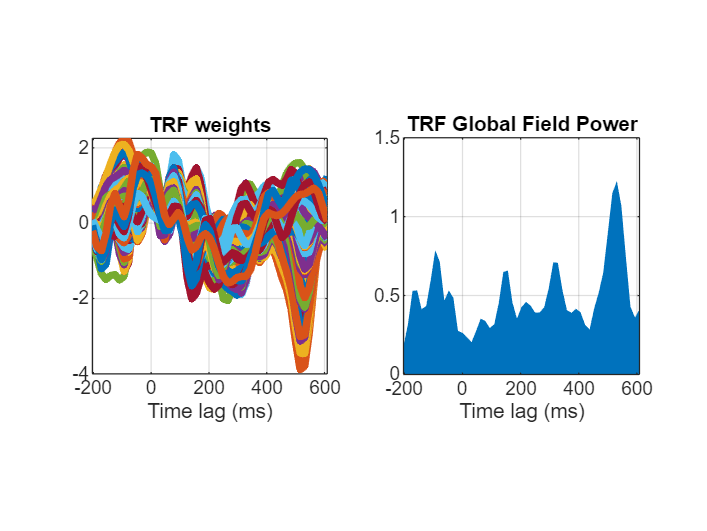


figure;
subplot(1,2,1)
mTRFplot(avgModel,'trf');
title('TRF weights')
grid on

% Plot GFP
subplot(1,2,2)
mTRFplot(avgModel,'gfp',[],'all');
title('TRF Global Field Power')
grid on